音声の読み込み

[audio_in, Fs] = audioread("guitar.wav");
n_audio = length(audio_in);     %音声ファイルの長さ
sound(audio_in,Fs)

設定

n_fft = 8196;                   %fft幅
n_shift =128;                  %シフト幅
frame_size = 1024;              %フレームサイズ

メインループ

audio_out = [];

n = n_fft - n_shift;

%バッファ
x_buff = zeros(n_fft,2);
y_buff = zeros(n_fft,2);

s_buff = zeros(n_fft,2);
s = 0;
s_amp = 0.005

s_amp = 0.0050


spectrum_buff= zeros(n_fft/2,2);

low = 0.5

low = 0.5000

high = 0.3;

tic;

for t = 1:frame_size:(n_audio-frame_size)
    
    x_frame = audio_in(t:t+frame_size,:);
    y_frame = zeros(frame_size,2);
    
    %メインの処理
    for i = 1:frame_size
        %OSCを進める
        s = mod(s + f/Fs, 1);
        s_buff(n,:) = (2*rand(1,2)-1)*s_amp;
        
        %バッファに音を入れる
        x_buff(n,:) = x_frame(i,:);
        
        %バッファから音を出す
        y_frame(i,:) = y_buff(max(1,n-n_fft/2),:);
        
        %ステップを進める
        n = n + 1;
        
        %バッファに音が溜まったら
        if n == n_fft
        
            %FFT
            x_fft_allfreq = fft(x_buff,n_fft);
            x_fft = x_fft_allfreq(1:end/2,:).*2;
            
            s_fft_allfreq = fft(s_buff,n_fft);
            s_fft = s_fft_allfreq(1:end/2,:).*2;
            
            %バッファを半分ずらす;
            x_buff(1:end-n_shift,:) = x_buff(n_shift+1:end,:);
            s_buff(1:end-n_shift,:) = s_buff(n_shift+1:end,:);
            
            %信号処理部
            amp = abs(x_fft);
            
            att_coeff = (low:(high-low)/(n_fft-1)*2:high).';
            
            if length(att_coeff) ~= n_fft
                coef_stereo = ones(n_fft,2)*(low+high)/2;
            else
                coef_stereo = [att_coeff att_coeff];
            end
            
            spectrum_buff = max((amp.*(att_coeff).^2+spectrum_buff)/2,spectrum_buff.*(att_coeff.^(n_shift/Fs)));
            
            y_fft = spectrum_buff.*s_fft;
           
            %信号処理部終わり

            %逆FFT
            y_buff = real(ifft(y_fft,n_fft));
            
            %位置の初期化
            n = n_fft-n_shift;
            
        end
    end
    
    if toc > 1/24
        %tiledlayout(2,1);
        %
        %nexttile;
        %plot(x_frame);
        %ylim([-1,1]);
        %xlim([-inf inf])
        %title("input frame")
        %
        %nexttile;
        %plot(y_frame);
        %ylim([-1,1]);
        %xlim([-inf inf])
        %title("output frame")
        %
        %drawnow;
        %
        %tic
    end
    audio_out = [audio_out; y_frame]; 
end

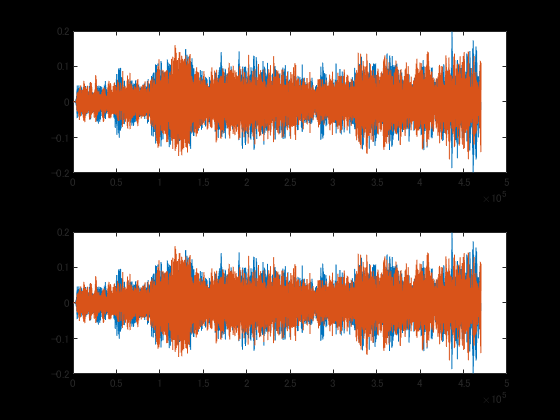

tiledlayout(2,1);
nexttile;
plot(audio_out);
title("input");

nexttile;
plot(audio_out);title("output")


soundsc(audio_out,Fs);